Capacitance Gauge Data Processing 

Author: Michael Noyce

Description: Program takes raw text files outputed from the CSIR wave tank facility and converts them into .csv files and plots the raw time series and  frequency spectra

Textfile = load("VTEST-5CM-2S-IRREG_0.txt")

Textfile = 1.0e+05 *

         0         0    0.0000         0         0
    0.0000    0.0000    0.0000         0         0
    0.0001    0.0000    0.0000         0         0
    0.0001    0.0000    0.0000         0         0
    0.0001    0.0000    0.0000         0         0
    0.0001    0.0000    0.0000         0         0
    0.0002    0.0000    0.0000         0         0
    0.0002    0.0000    0.0000         0         0
    0.0002    0.0000    0.0000         0         0
    0.0003    0.0000    0.0000         0         0


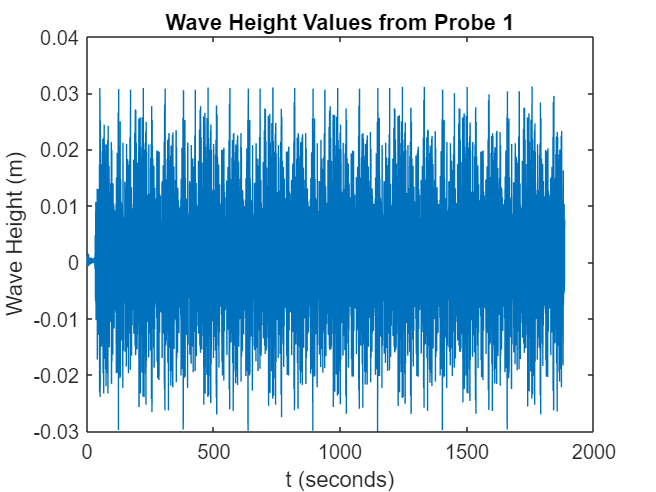

writematrix(Textfile, "VTEST-5CM-2S-IRREG_0.csv");
CapacitanceData = readtable("VTEST-5CM-2S-IRREG_0.csv");

Fs = 100; %Guages are sampled at 25Hz or 50 Hz
T = 1/Fs;

timeStamp = CapacitanceData{:, 2}*10; %Correction (time series off by a factor of 10)
probe1Height = CapacitanceData{:, 3};
probe2Height = CapacitanceData{:, 4};

%Differentaite to get acceleration
probe_1_velocity = gradient(probe1Height, T);
probe_1_acceleration = gradient(probe_1_velocity, T);

plot(timeStamp, probe1Height)
title('Wave Height Values from Probe 1')
xlabel('t (seconds)')
ylabel('Wave Height (m)')

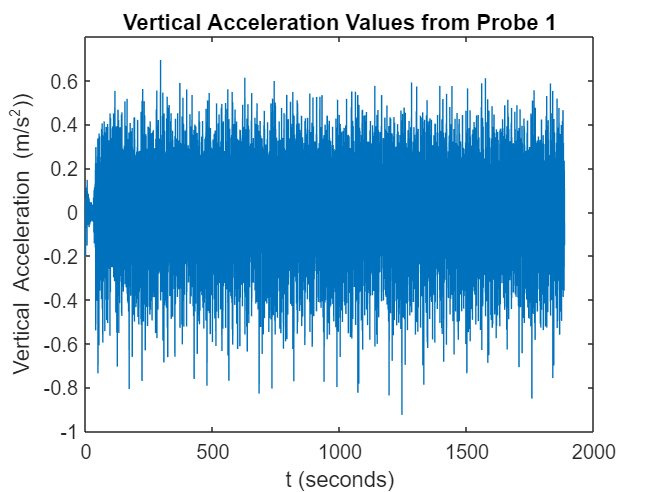


plot(timeStamp, lowpass(probe_1_acceleration, 2, Fs) )
title('Vertical Acceleration Values from Probe 1')
xlabel('t (seconds)')
ylabel('Vertical Acceleration (m/s^2))')

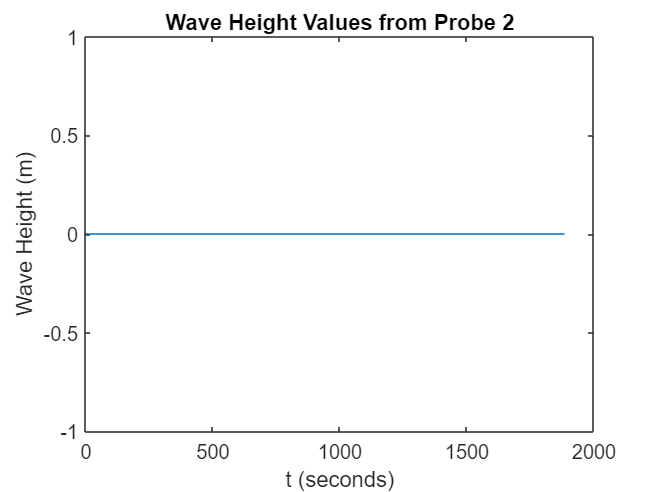


plot(timeStamp, probe2Height)
title('Wave Height Values from Probe 2')
xlabel('t (seconds)')
ylabel('Wave Height (m)')


WaveSpectra = fft(probe1Height);
L = length(probe2Height);
P2 = abs(WaveSpectra/L);
P1 = P2(1:L/2+1);

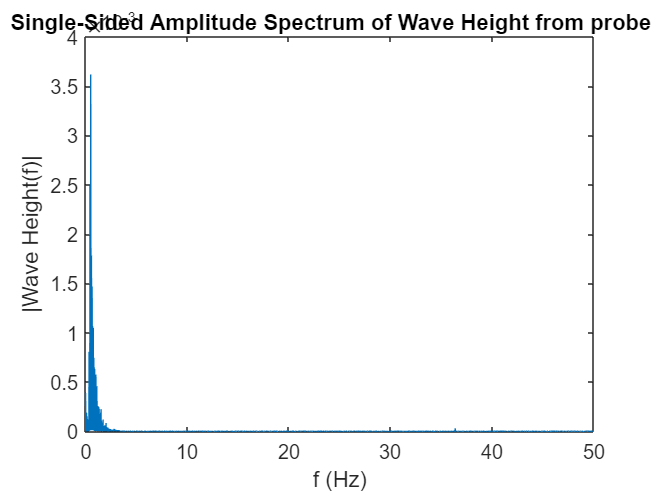

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Wave Height from probe 1')
xlabel('f (Hz)')
ylabel('|Wave Height(f)|')


%probe_1_acceleration = lowpass(probe_1_acceleration, 2, Fs);

WaveSpectra = fft(probe_1_acceleration);
L = length(probe_1_acceleration);
P2 = abs(WaveSpectra/L)/Fs;
P1 = P2(1:L/2+1);

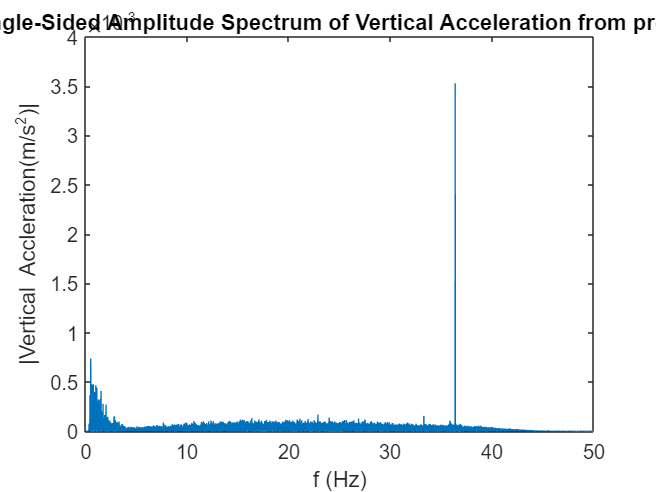

P1(2:end-1) = 2*P1(2:end-1)*2;
f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of Vertical Acceleration from probe 1')
xlabel('f (Hz)')
ylabel('|Vertical Accleration(m/s^2)|')



%%Wave Height Calculation
f1 = 0.2; %Lower corner frequency for half cosine taper
f2 = 0.3; %Upper frequency for half cosine taper
fc = 10; %Nyquist Frequency


Nfft = length(probe_1_acceleration);
f = Fs*(-Nfft/2:1:Nfft/2-1)'./Nfft

f =   -50.0000
  -49.9995
  -49.9989
  -49.9984
  -49.9979
  -49.9973
  -49.9968
  -49.9963
  -49.9958
  -49.9952


N = size(f, 1); 

y = fft(probe_1_acceleration);

%Fourier filter 
% Rf = response frequency weights
Rf = zeros(N, 1);


for i = 1:length(f)
    if f(i) < f1 
       Rf(i, 1) = 0;
    end
        if f(i) > f1 & f(i) < f2
            Rf(i, 1) = (1/2)*(1-cos(pi*(f(i)-f1)/(f2-f1)))*(-1/(2*pi*f(i)).^2);
        end
            if f(i) > f2 & f(i) < fc
                Rf(i, 1) = -1/(2*pi*f(i)).^2; 
            end
end


waveHeight = ifft(fftshift(y.*Rf));
t_trunc = (0:length(waveHeight)-1)*T;        % Time vector


plot(t_trunc, waveHeight) 

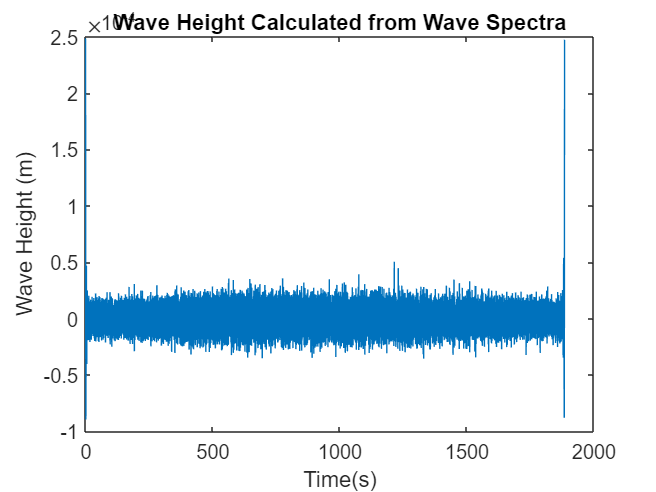

title('Wave Height Calculated from Wave Spectra')
xlabel('Time(s)')
ylabel('Wave Height (m)')


PSD = pwelch(waveHeight);
L = length(P2);
f = Fs*(0:(L/2))/L;



